Declaramos las variables.

syms x
f = x^3 - 5*x^2 + 7*x - 3;
xest = 0;
ermax = 1e-5;

Dibujamos la función para hacernos una idea del problema que estamos resolviendo.

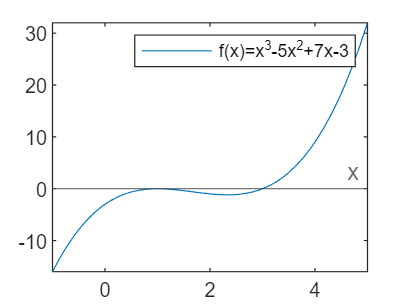

fplot(f, [-1, 5])
hold on
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos la raíz próxima a cero con ambos métodos.

% Función Newton-Rapson modificada
[r_mod, i_mod] = newtonmod(f, xest, ermax);

erit: 0.333929 => ermax: 0.000010
erit: 0.160578 => ermax: 0.000010
erit: 0.100498 => ermax: 0.000010
erit: 0.070780 => ermax: 0.000010
erit: 0.053387 => ermax: 0.000010
erit: 0.042131 => ermax: 0.000010
erit: 0.034339 => ermax: 0.000010
erit: 0.028676 => ermax: 0.000010
erit: 0.024405 => ermax: 0.000010
erit: 0.021089 => ermax: 0.000010
erit: 0.018454 => ermax: 0.000010
erit: 0.016318 => ermax: 0.000010
erit: 0.014560 => ermax: 0.000010
erit: 0.013091 => ermax: 0.000010
erit: 0.011850 => ermax: 0.000010
erit: 0.010791 => ermax: 0.000010
erit: 0.009877 => ermax: 0.000010
erit: 0.009083 => ermax: 0.000010
erit: 0.008388 => ermax: 0.000010
erit: 0.007776 => ermax: 0.000010
erit: 0.007233 => ermax: 0.000010
erit: 0.006749 => ermax: 0.000010
erit: 0.006316 => ermax: 0.000010
erit: 0.005926 => ermax: 0.000010
erit: 0.005574 => ermax: 0.000010
erit: 0.005255 => ermax: 0.000010
erit: 0.004965 => ermax: 0.000010
erit: 0.004699 => ermax: 0.000010
erit: 0.004456 => ermax: 0.000010
erit: 0.004233

% Función de clase
[r_clase, i_clase] = newton_rapson_tol_sol( ...
    matlabFunction(f), ...
    matlabFunction(diff(f)), ...
    xest, ermax);

Mostramos los resultados con 6 decimales.

fprintf("Raíz método clase: %.6f", r_clase);

Raíz método clase: 0.999994

fprintf("Se han requerido %d iteraciones.", i_clase);

Se han requerido 18 iteraciones.

fprintf("Raíz método modificado: %.6f", r_mod);

Raíz método modificado: 0.972707

fprintf("Se han requerido %d iteraciones.", i_mod);

Se han requerido 1454 iteraciones.

Gráficamente:

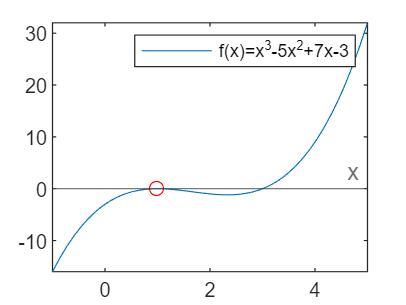

fplot(f, [-1, 5])
fx = matlabFunction(f);
hold on
plot(r_mod, fx(r_mod), 'ro')
yline(0, '-', 'x')
legend({'f(x)=x^{3}-5x^{2}+7x-3'})
hold off

Calculamos el porcentaje en el que difieren:

dif_r = abs((r_mod - r_clase) / r_clase) * 100;
fprintf("Las raíces calculadas difieren en un %.2f%%", dif_r);

Las raíces calculadas difieren en un 2.73%